# Ejercicio 5.1

**Jose Antonio Lorencio Abril**

## a)

Por un lado tenemos $F=m\cdot x''$ y por otro $F=-k\cdot x-c\cdot x'$. Es decir, $m\cdot x'' = -k\cdot x-c\cdot x' \iff k\cdot x+c\cdot x'+m\cdot x''=0$. 

Sustituyendo los valores concretos del enunciado, obtenemos la ecuación diferencial $k\cdot x+c\cdot x'+3.3x''=0$.

Y vamos a resolverla, aplicando las condiciones iniciales:

syms x(t)
dx = diff(x,1)

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$


syms k, syms c
ode = k*x+c*diff(x,1)+3.3*diff(x,2)==0

$$ode(t) = \frac{33\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{10}+c\,\frac{\partial }{\partial t}x\left(t\right)+k\,x\left(t\right)=0$$

xSol(t) = dsolve(ode, [x(0)==1 dx(0)==0])

$$xSol(t) = \begin{array}{l} \frac{\sqrt{5}\,{\mathrm{e}}^{-t\,\left(\frac{5\,c}{33}-\frac{\sqrt{5}\,\sigma_{1}}{33}\right)}\,\left(5\,c+\sqrt{5}\,\sigma_{1}\right)}{10\,\sigma_{1}}-\frac{{\mathrm{e}}^{-t\,\left(\frac{5\,c}{33}+\frac{\sqrt{5}\,\sigma_{1}}{33}\right)}\,\left(\sqrt{5}\,c-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{5\,c^{2}-66\,k} \end{array}$$

## b)

Ahora introducimos los datos:

time = [0,2,4,6,8,10]

time =      0     2     4     6     8    10


dis = [1, 0.559, 0.258, 0.118, 0.054, 0.025]

dis =     1.0000    0.5590    0.2580    0.1180    0.0540    0.0250


Y lo ploteamos:

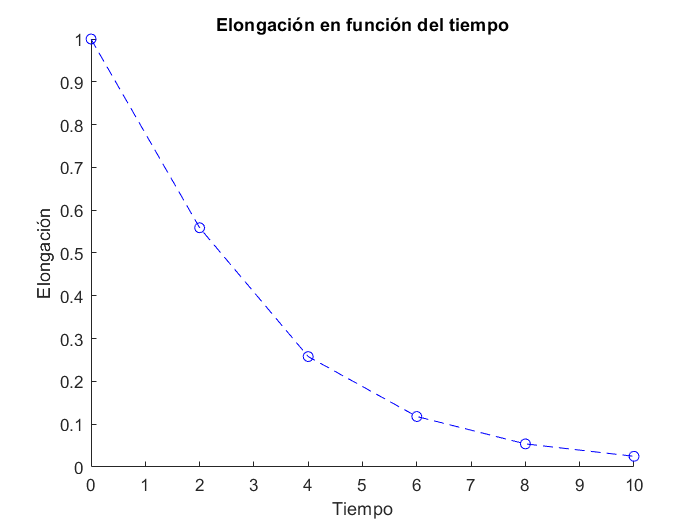

figure(1)
hold on
plot(time, dis, 'o--b')
title('Elongación en función del tiempo')
xlabel('Tiempo')
ylabel('Elongación')
hold off

Por lo que se observa en la gráfica, el comportamiento será sobreamortiguado o críticamente amortiguado, aunque esta condición es muy fuerte y complicado que se dé exactamente en un caso práctico.

## c)

Por último, vamos a calcular $k$ y $c$, usando mínimos cuadrados.

func = matlabFunction(xSol);
func2 = @(a, T) func(T, a(1), a(2))

func2 = function_handle with value:
    @(a,T)func(T,a(1),a(2))


x0 = [1, 1];
a = lsqcurvefit(func2, x0, time, dis)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


a =    8.2468 - 0.0000i   2.7143 - 0.0000i


Es decir, tenemos que $c=8.2468$ y $k=2.7143$. 

Para visualizar el ajuste, ploteamos:

tt = 0:0.5:10;
ft = func2(a,tt);

figure(2)
hold on
plot(time, dis, 'or')
plot(tt, ft, 'LineStyle',"-")

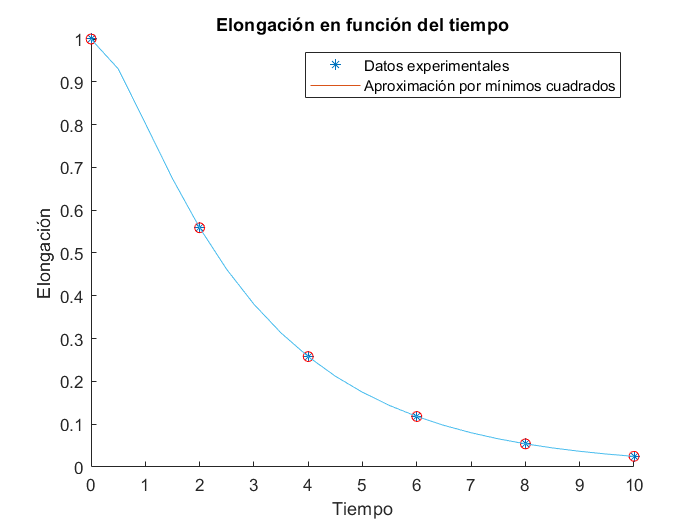

legend('Datos experimentales', 'Aproximación por mínimos cuadrados')
title('Elongación en función del tiempo')
xlabel('Tiempo')
ylabel('Elongación')
hold off

El ajuste es muy bueno.

Comprobemos si es sobreamortiguado:

del = a(1)^2-4*3.3*a(2)

del = 32.1815 - 0.0000i

Obteniendo $\Delta = 32.1815 > 0$, que es claramente un caso sobreamortiguado, como conjeturamos en el apartado b.